clear;
close all;
clc;

% The root directory of the dataset
root_dir = fullfile("p_dataset_26/");

% Load the dataset 
dataset = imageDatastore(root_dir, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Counting the number of images for every label and displaying it on a table
table = countEachLabel(dataset);
disp(table);

    Label    Count
    _____    _____

      0       254 
      4       254 
      7       254 
      8       254 
      A       254 
      D       254 
      H       254 



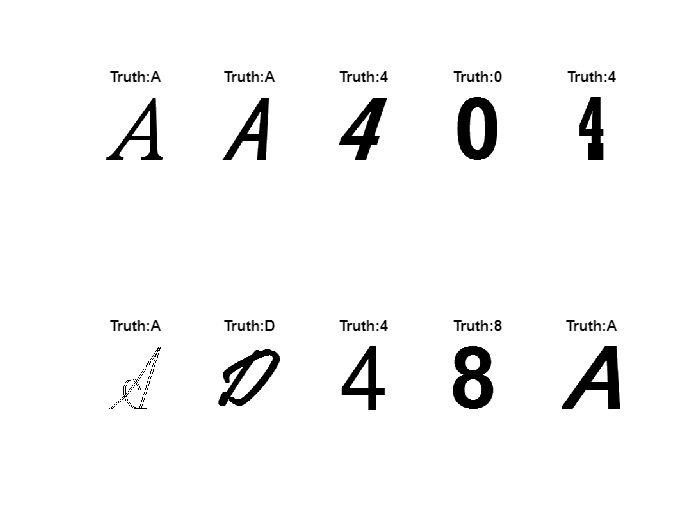


% Randomize 10 numbers and generate total number of images in the dataset 
random__num = randperm(sum(table.Count), 10);
figure;
for i = 1:10 
    subplot(2, 5, i);
    imshow(dataset.Files{random__num(i)}); % Divide into 2x5 grid of subplot
    title(['Truth:' char(dataset.Labels(random__num(i)))]);
end

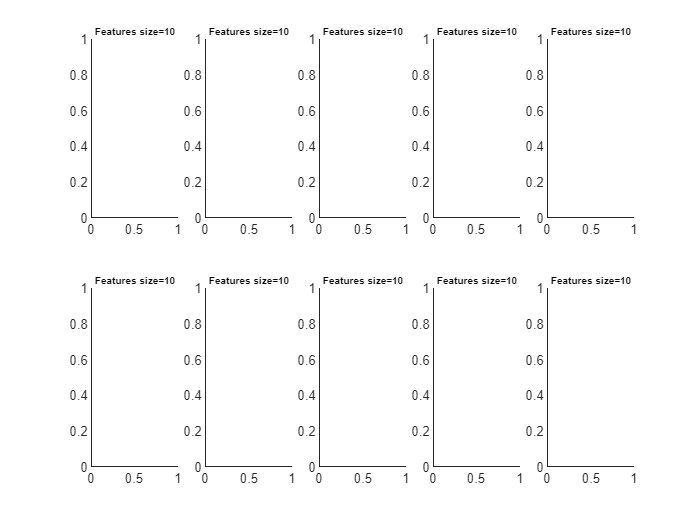



% Visualizing LBP features extracted
figure;
for i = 1:10
    subplot(2, 5, i);
    img = readimage(dataset, random__num(i));
    lbpFeatures = customExtractLBPFeatures(img);
    % Plot or visualize LBP features as you prefer
    % plot(lbpFeatures) % You might need to change this depending on how you want to visualize LBP features
    title(['Features size=' num2str(length(lbpFeatures))], 'Fontsize', 6);
end


% Dividing the dataset into training set and test (validation) set 
% Training set: test set = 0.75 : 0.25
[trainset, testset] = splitEachLabel(dataset, 0.75, "randomized");

% Initializing parameters for feature extraction from training set
train_num = numel(trainset.Files);
lbpFeatures = customExtractLBPFeatures(readimage(trainset, 1)); % Determine the feature vector size of LBP
lbp_feat_size = length(lbpFeatures);
train_feat = zeros(train_num, lbp_feat_size, 'single'); % Using single data type to save memory 
train_labels = trainset.Labels;

% Training the dataset
% The actual extraction of LBP features from each image in the training set
for i = 1:train_num
    img = readimage(trainset, i);
    train_feat(i,:) = customExtractLBPFeatures(img);
end

SVM = fitcecoc(train_feat, train_labels); % Train using binary SVM classifiers in one vs all scheme

% Obtaining the accuracy of the SVM
test_num = numel(testset.Files); % Initializing variable for test dataset 
test_feat = zeros(test_num, lbp_feat_size, 'single'); % Note: Using lbp_feat_size

for j = 1:test_num % Extracting LBP features from the test images 
    img = readimage(testset, j);
    test_feat(j, :) = customExtractLBPFeatures(img);
end

predicted_label = predict(SVM, test_feat); % Predicting labels using SVM classifiers 

clc;
test_label = testset.Labels;
accuracy = sum(predicted_label == test_label) / numel(test_label);
disp(accuracy);

    0.3605



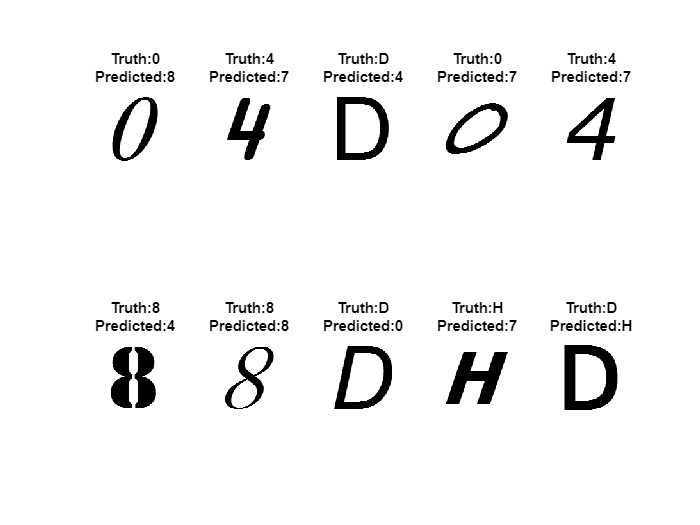


% Predicted Labels vs Actual Labels
random_num = randperm(numel(predicted_label), 10);
figure;
for i = 1:10
    subplot(2, 5, i);
    imshow(testset.Files{random_num(i)});
    title({['Truth:' char(test_label(random_num(i)))], ['Predicted:' char(predicted_label(random_num(i)))]});
end

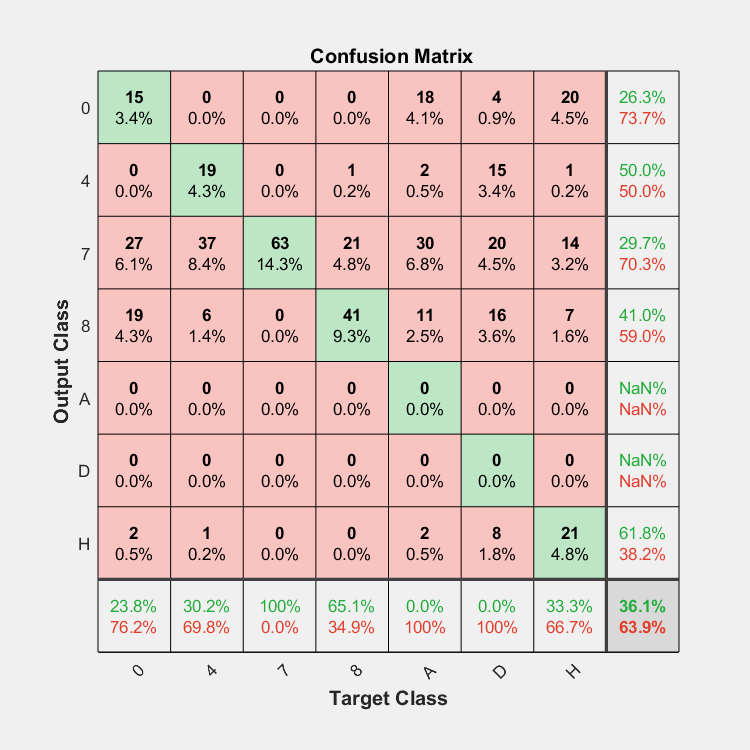


% Confusion Matrix for evaluating performance
figure;
plotconfusion(test_label, predicted_label);

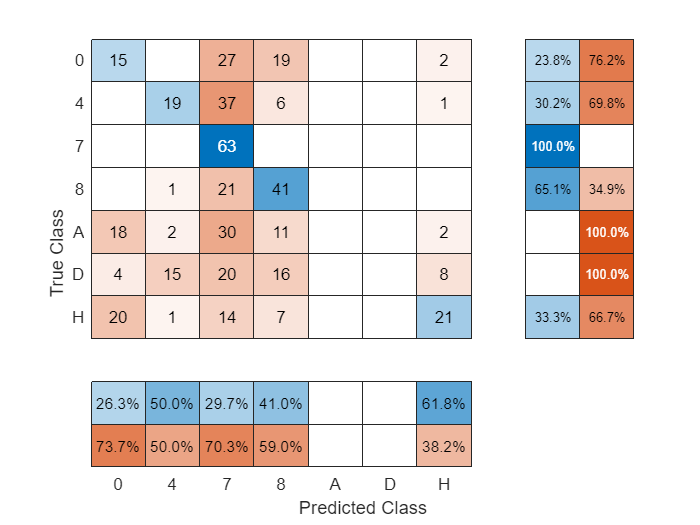


% Confusion chart for evaluating performance
figure;
chart = confusionchart(test_label, predicted_label, 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');


% Custom Function to extract LBP Features

% Saving SVM
SVM_LBP = SVM;
save SVM_LBP

function lbpFeatures = customExtractLBPFeatures(img)
    % Convert image to grayscale if it is not already
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    
    lbpFeatures = extractLBPFeatures(img, 'Upright', false);
end



